clc
clear 
close all

out = load("sim_save.mat").out;
out_2 = load("sim_save_2.mat").out;
load("modelo_joao.mat")

#### Comparação das variáveis entre as simulações

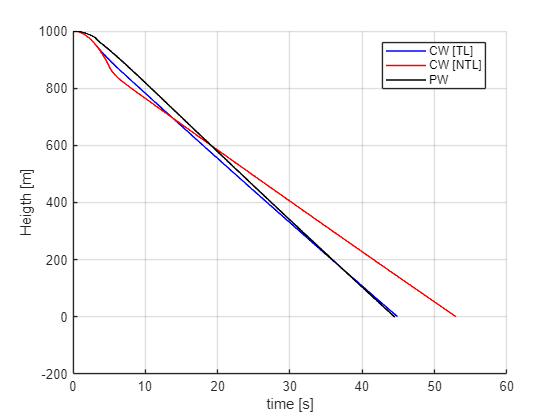

figure()
hold on
plot(out.main_clock, out.vehicle_position(:, 3), 'b', 'LineWidth', 1.2, 'DisplayName', 'CW [TL]') % linha preta
plot(out_2.main_clock, out_2.vehicle_position(:, 3), 'r', 'LineWidth', 1.2, 'DisplayName', 'CW [NTL]') % linha preta
plot(t_final, h_final, 'k', 'LineWidth', 1.2, 'DisplayName', 'PW') % linha vermelha
grid on
xlabel('time [s]')
ylabel('Heigth [m]')
hold off;
legend("Location","best")

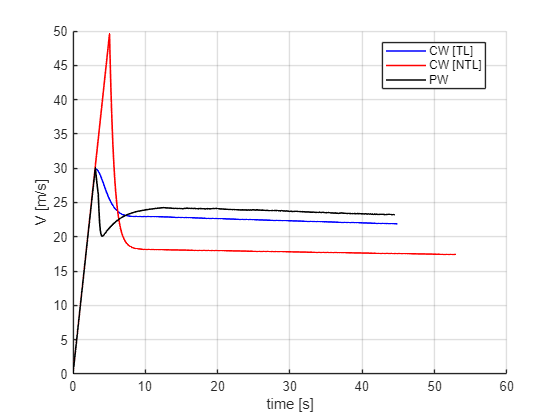

figure()
hold on
plot(out.main_clock, -out.vehicle_velocity(:, 3), 'b', 'LineWidth', 1.2, 'DisplayName', 'CW [TL]') % linha preta
plot(out_2.main_clock, -out_2.vehicle_velocity(:, 3), 'r', 'LineWidth', 1.2, 'DisplayName', 'CW [NTL]') % linha preta
plot(t_final, v_final, 'k', 'LineWidth', 1.2, 'DisplayName', 'PW') % linha vermelha
grid on
xlabel('time [s]')
ylabel('V [m/s]')
hold off;
legend("Location","best")

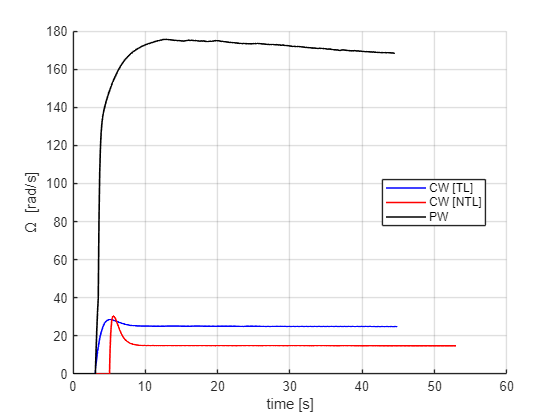

figure()
hold on
plot(out.main_clock, out.rotor_velocity, 'b', 'LineWidth', 1.2, 'DisplayName', 'CW [TL]') % linha preta
plot(out_2.main_clock, out_2.rotor_velocity, 'r', 'LineWidth', 1.2, 'DisplayName', 'CW [NTL]') % linha preta
plot(t_final, w_final, 'k', 'LineWidth', 1.2, 'DisplayName', 'PW') % linha vermelha
grid on
xlabel('time [s]')
ylabel('\Omega [rad/s]')
hold off;
legend("Location","best")

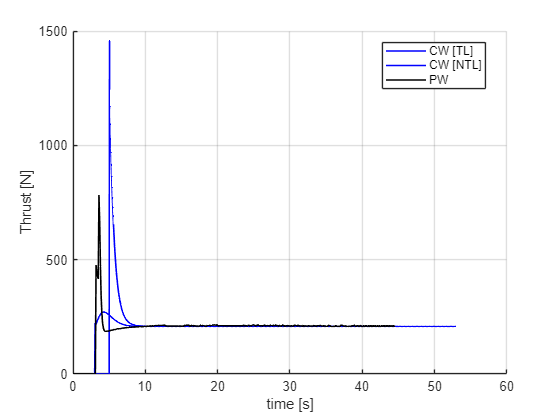

figure()
hold on
plot(out.main_clock, out.F_rotor(:, 3), 'b', 'LineWidth', 1.2, 'DisplayName', 'CW [TL]') % linha preta
plot(out_2.main_clock, out_2.F_rotor(:, 3), 'b', 'LineWidth', 1.2, 'DisplayName', 'CW [NTL]') % linha preta
plot(t_final, thrust_final, 'k', 'LineWidth', 1.2, 'DisplayName', 'PW') % linha vermelha
grid on
xlabel('time [s]')
ylabel('Thrust [N]')
hold off;
legend("Location","best")

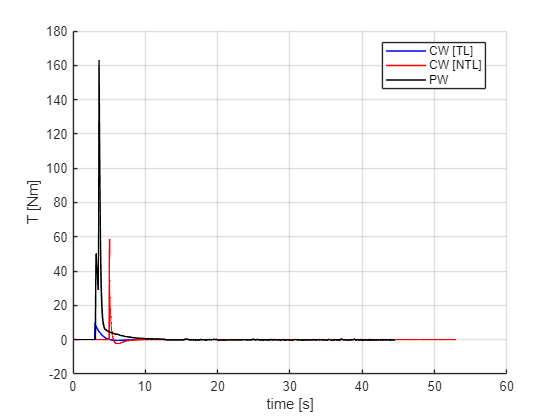

figure()
hold on
plot(out.main_clock, out.T_rotor, 'b', 'LineWidth', 1.2, 'DisplayName', 'CW [TL]') % linha preta
plot(out_2.main_clock, out_2.T_rotor, 'r', 'LineWidth', 1.2, 'DisplayName', 'CW [NTL]') % linha preta
plot(t_final,torque_final, 'k', 'LineWidth', 1.2, 'DisplayName', 'PW') % linha vermelha
grid on
xlabel('time [s]')
ylabel('T [Nm]')
hold off;
legend("Location","best")

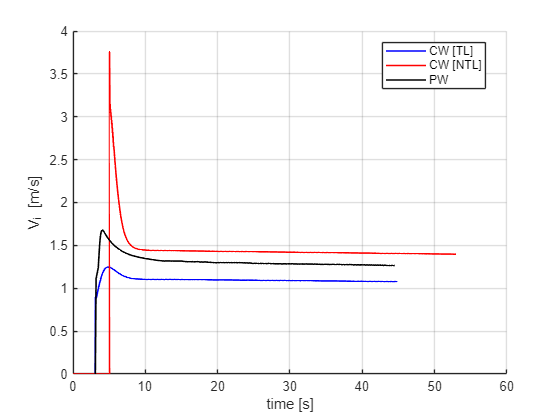

figure()
hold on
plot(out.main_clock, -out.rotor_induced_velocity, 'b', 'LineWidth', 1.2, 'DisplayName', 'CW [TL]') % linha preta
plot(out_2.main_clock, -out_2.rotor_induced_velocity, 'r', 'LineWidth', 1.2, 'DisplayName', 'CW [NTL]') % linha preta
plot( t, vi_vec, 'k', 'LineWidth', 1.2, 'DisplayName', 'PW') % linha vermelha
grid on
xlabel('time [s]')
ylabel('V_i [m/s]')
hold off;
legend("Location","best")

#### COMPARAÇÃO ENTRE OUTRAS VARIÁVEIS

R = 1.1;
A = pi * R^2

A = 3.8013

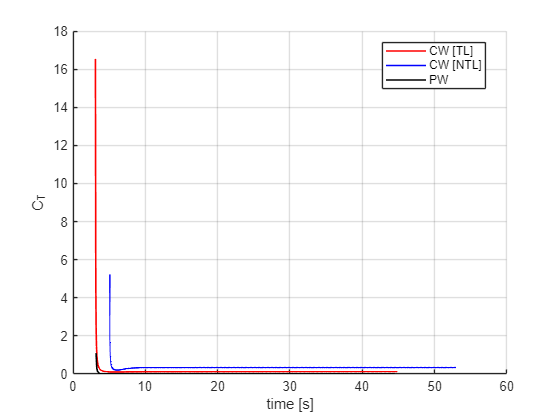

rho = 1.225;

T_cw_tl = out.F_rotor(:,3);
TV_cw_tl = out.rotor_velocity * R;

T_cw_ntl = out_2.F_rotor(:,3);
TV_cw_ntl = out_2.rotor_velocity * R;
T_pw = thrust_final;
TV_pw = R * w_final;

CT_cw_tl = T_cw_tl./(0.5 * rho * TV_cw_tl.^2 * A);
CT_cw_ntl = T_cw_ntl./(0.5 * rho * TV_cw_ntl.^2 * A);
CT_pw = T_pw./(0.5 * rho * TV_pw.^2 * A);

figure()
hold on
plot(out.main_clock, CT_cw_tl, 'r', 'LineWidth', 1.2, 'DisplayName', 'CW [TL]')
plot(out_2.main_clock, CT_cw_ntl, 'b', 'LineWidth', 1.2, 'DisplayName', 'CW [NTL]')
plot(t_final, CT_pw, 'k', 'LineWidth', 1.2, 'DisplayName', 'PW')
grid on
hold off
xlabel('time [s]')
ylabel('C_T')
legend("Location","best")